## CODICE MATLAB

Per presentare i risultati e confrontarli con quelli del paper per confermarne la correttezza, dobbiamo, per prima cosa andare ad estrapolare le informazioni che ci servono dal dataset. Ci andiamo, quindi, a creare un'unica tabella che chiameremo `dati_B3`

### 1. CREAZIONE DATASET

%% --- CREAZIONE DEL NOSTRO DATASET ---
% inizializzazione
clear
close all 
clc

% lista dei FILE SCARICATI e i rispettivi TICKER
files = {
    'VALE3_dati_storici.csv', 'VALE3';
    'ITUB4_dati_storici.csv', 'ITUB4';
    'PETR4_dati_storici.csv', 'PETR4';
    'B3SA3_dati_storici.csv', 'B3SA3';
    'BBDC4_dati_storici.csv', 'BBDC4';
    'PETR3_dati_storici.csv', 'PETR3';
    'ABEV3_SA_dati_storici.csv', 'ABEV3';
    'ITSA4_dati_storici.csv', 'ITSA4';
    'WEGE3_dati_storici.csv', 'WEGE3';
    'ODPV3_dati_storici.csv', 'ODPV3';
    'IBOVESPA_dati_storici.csv', 'IBOV'
};


% inizializziamo una TIMETABLE vuota
TimeTable = [];

for i = 1:size(files, 1)
    filename = files{i, 1};
    ticker = files{i, 2};
    
    % leggiamo il file riga per riga e manteniamo i nomi originali delle colonne
    righe = readtable(filename, 'PreserveVariableNames', true);
    
    % datetime --> funzione che ci permette di spiegare a MatLab che i
    %              primi due numeri sono il mese, poi il giorno e poi l'anno
    date = datetime(string(righe.Date), 'InputFormat', 'MM/dd/yyyy');
    
    % OSS. --> questo perchè Investing.com in alcuni prezzi invece di usare il punto per le migliaia, 
    %          utilizza la virgola, pertanto Matlab se provasse a leggere tale numero andrebbe in errore credendo sia un testo
    %
    % OSS. --> la condizione if ci serve per dire a MatLab di fare attenzione 
    %          ai prezzi che sono scritti in formato di testo (celle o stringhe)
    %
    % strrep     --> funzione che ci permette di rimuovere le virgole usate
    %                come separatori delle migliaia
    %
    % str2double --> converte la stringa in un double
    prezzi = righe.Price;
    if iscell(prezzi) || isstring(prezzi)
        prezzi_str = strrep(string(prezzi), ',', ''); 
        prezzi = str2double(prezzi_str); 
    end
    
    % creazione TIMETABLE e ORDINE CRONOLOGICO LOGICO (dal 2011 al 2021)
    % OSS. --> - timetable: ci permette di unire le date e i prezzi,
    %            utilizzando come variabile principale il tempo
    %          - sortrows: ci permette di ribaltare l'ordine dei dati,
    %            siccome Investing.com ce li dà dal 2021 al 2011
    TT = timetable(date, prezzi, 'VariableNames', {ticker});
    TT = sortrows(TT);
    
    % uniamo i dati attraverso la funzione synchronize()
    % OSS. --> synchronize: cerca le date uguali e le allinea sulla stessa
    %          riga (ad esempio se ci sono degli asset scambiati lo stesso giorno)
    if isempty(TimeTable)
        TimeTable = TT;
    else
        TimeTable = synchronize(TimeTable, TT, 'union');
    end
end

% --- aggiunta del TASSO RISK-FREE (SELIC) ---

% carichiamo il file scaricato dal portale SGS
% OSS. --> il file usa il punto e virgola come delimitatore
selic_raw = readtable('SELIC_dati_storici.csv', 'Delimiter', ';', 'PreserveVariableNames', true);

% rimuoviamo l'ultima riga che contiene la parola "Source"
if contains(string(selic_raw{end, 1}), 'Source')
    selic_raw(end, :) = [];
end

% formattazione delle date SELIC
% OSS. --> a differenza di Investing.com , la Banca Centrale Brasiliana usa il formato dd/MM/yyyy
date_selic = datetime(string(selic_raw{:, 1}), 'InputFormat', 'dd/MM/yyyy');

% troviamo e teniamo solo le date valide (quindi cerchiamo se ci sono
% buchi nel vettore delle date del SELIC i cosiddetti NaT, cioè Not-a-Time)
idx_valide = ~isnat(date_selic);
date_selic = date_selic(idx_valide); % manteniamo solo le date pulite

% formattazione dei tassi SELIC
tassi_selic = selic_raw{idx_valide, 2};

% gestione delle virgole per i decimali
if iscell(tassi_selic) || isstring(tassi_selic)
   tassi_str = strrep(string(tassi_selic), ',', '.'); 
   tassi_selic = str2double(tassi_str);
end

% OSS. IMPORTANTE --> il tasso SELIC nel file è espresso in percentuale (es. 0.0402%). Lo dividiamo per 100 
%                     per ottenere il numero decimale puro (es. 0.000402) da usare nelle nostre equazioni del modello MPC.
tassi_selic = tassi_selic / 100;

% creazione Timetable e Sincronizzazione
TT_selic = timetable(date_selic, tassi_selic, 'VariableNames', {'SELIC'});
TimeTable = synchronize(TimeTable, TT_selic, 'union');

% RIMUOVIAMO eventuali giorni festivi in cui mancano i cambi
% OSS. --> rmmissing: ci permette di rimuove le righe che presentano
%          valori NaN, così da avere una matrice densa al 100%
TimeTable = rmmissing(TimeTable);

% SALVATAGGIO della tabella in file csv
writetimetable(TimeTable, 'dati_B3.csv');

### 3. BLOCCO DI CODICE: FIGURE 2, 3A, 3B

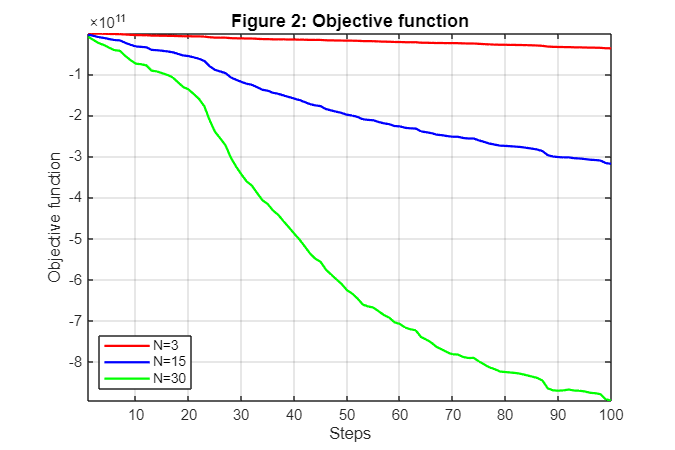

% --- FIGURA 2 e 3: Valori della Funzione Obiettivo e Costi di Transazione ---

% inizializzazione
clear
clc

% --- CARICAMENTO DATI dal dataset ---
data = readtable('dati_B3.csv', 'PreserveVariableNames', true);

% estraiamo solo i 10 asset rischiosi e il tasso SELIC, cioè escludiamo l'indice Ibovespa (e le date)
prezzi = data{:, 2:11};
selic_storico = data.SELIC;      % estraiamo il tasso risk-free

n_giorni = size(prezzi, 1); 
n_assets_risk = size(prezzi, 2); % 10 asset (rischiosi)
n_vars = n_assets_risk + 1;      % 11 variabili (u0 + 10 azioni)

% calcolo dei rendimenti logaritmici (equazione 3 del paper)
% OSS. --> gli autori usano i rendimenti logaritmici. In finanza e nei modelli stocastici, il logaritmo smorza l'effetto dei dati anomali (outliers) e 
%          rende i rendimenti additivi nel tempo. Andiamo, quindi, a svolgere proprio questo convertendo i prezzi del dataset prima creato
rendimenti = log(prezzi(2:end, :) ./ prezzi(1:end-1, :));

% --- Inizializzazione dei PARAMETRI DEL MODELLO ---
w0 = 100000;                              % capitale iniziale investito R$ (real brasiliano)
mu_0_annuale = 0.15;                      % tasso composto desiderato (15%)

% tasso giornaliero di riferimento
% OSS. --> poichè il paper richiede un tasso del 15% annuo, ma il nostro controllore ragiona in "giorni", 
%          dobbiamo convertirlo in tasso giornaliero andando ad utilizzare la radice 252-esima (i giorni lavorativi di Borsa in un anno)
mu_0 = (1 + mu_0_annuale)^(1/252) - 1;    

% frazione di costo di transazione (0.04%)
% OSS. --> solo per le azioni (risk asset)
c_risk = 0.0004; 

% creiamo un vettore dei costi:
%   - 0 per u0 (risk-free asset)
%   - 0.0004 per risk asset
c_vec = [0; repmat(c_risk, n_assets_risk, 1)];

% matrice R per i costi quadratici
% OSS. --> penalità infinitesima anche su u0 per stabilità numerica di fmincon
R_cost = diag([1e-6; repmat(1e-5, n_assets_risk, 1)]); 
rho = 1e5; % peso di penalizzazione per tracking inferiore al target (adeguato per i valori presentati in Figura 2)

% OSS. --> gli autori per la Figura 2 (e anche per la Figura 3) usano N = 3, 15, 30
N_list = [3, 15, 30];

% parametri di simulazione
start_k = 60;
giorni_simulazione = 100; % --> test reale: size(rendimenti, 1) - start_k;

% buffer per il salvataggio dei risultati
J_storico = zeros(giorni_simulazione, length(N_list));
Quad_Cost_storico = zeros(giorni_simulazione, length(N_list));
True_Cost_storico = zeros(giorni_simulazione, length(N_list));

% utilizziamo Sequential Quadratic Programming (SQP)
% OSS. --> l'algoritmo SQP approssima iterativamente la nostra funzione di costo (non lineare) e gestisce i vincoli 
options = optimoptions('fmincon', 'Algorithm', 'sqp', 'Display', 'none', 'MaxFunctionEvaluations', 5000);

% --- ADDESTRAMENTO VAR(1) (sui primi 60 giorni) ---
% OSS. --> stima la matrice A1 sui 60 giorni precedenti al tracking
train_data = rendimenti(1:60, :);

% creiamo la struttura del modello VAR: n_asset_risk variabili, ordine VAR=1
% OSS. --> funzione varm() preferita a vgxvarx() scelta dagli autori,
%          perchè ha una sintassi più semplice ed è una funzione più recente che
%          svolge gli stessi compiti
modelloVAR = varm(n_assets_risk, 1);

% stimiamo il modello definito
% OSS. --> funzione estimate() prende l'architettura del modelloVAR e la
%          associa ai dati di addestramento "train_data"
stima_modelloVAR = estimate(modelloVAR, train_data, 'Display', 'off');

% estraiamo la matrice dei coefficienti A1
% OSS. --> estraiamo la matrica A1, che come specificato dagli autori,rimarrà costante per tutti i giorni di simulazione.
%          Ricalibreremo dinamicamente, come evidenziato dagli autori, solo l'interetta (v_hat)
A1 = stima_modelloVAR.AR{1};


% --- loop MPC ---
for j = 1:length(N_list)
    N = N_list(j);
    
    % inizializzazione per l'orizzonte in questione
    w_k = w0;                   % ricchezza attuale
    w_ref = w0;                 % ricchezza target (reference)
    u_prev = zeros(n_vars, 1);  % allocazioni al giorno precedente

    for step = 1:giorni_simulazione
        k = start_k + step - 1;

        % finestra mobile di 60 giorni
        % --> stimiamo i rendimenti futuri usando la media campionaria recente
        % --> quindi, ricalibriamo il termine noto (v_hat) con la media mobile recente
        mu_hat = mean(rendimenti(k-59:k, :))';
        v_hat = (eye(n_assets_risk) - A1) * mu_hat;
        
        % previsione ricorsiva dei rendimenti futuri sull'orizzonte N
        eta_pred = zeros(n_assets_risk, N);
        eta_curr = rendimenti(k, :)';
        
        for h = 1:N
            if h == 1
                eta_pred(:, h) = v_hat + A1 * eta_curr;
            else
                eta_pred(:, h) = v_hat + A1 * eta_pred(:, h-1);
            end
        end

        % definiamo il tasso risk-free atteso come il tasso di SELIC al giorno k
        r1_hat = selic_storico(k);

        % impostazione Variabili Decisionali iniziali
        u_init = repmat(w_k / n_vars, n_vars * N, 1); 
        
        % OSS. --> non è possibile vendere allo scoperto
        lb = zeros(n_vars * N, 1);    
        
        % OSS. --> upper bound gestite dalla funzione locale vincoli_mpc
        ub = []; 

        % risoluzione del Problema di Controllo Ottimo (OCP)
        cost_func = @(U) calcolo_mpc_cost(U, w_k, u_prev, eta_pred, r1_hat, mu_0, N, n_assets_risk, R_cost, rho);
        vincoli_func = @(U) vincoli_mpc(U, w_k, eta_pred, r1_hat, N, n_assets_risk);
        
        [U_opt, J_val] = fmincon(cost_func, u_init, [], [], [], [], lb, ub, vincoli_func, options);

        % applicazione dell'azione di controllo e avanzamento
        % OSS. --> prendiamo solo l'allocazione del primo giorno
        u_app = U_opt(1:n_vars);
        
        % --- Calcolo COSTO QUADRATICO TOTALE PREVISTO (per Figura 3A) ---
        quad_total_N = 0;
        u_last_temp = u_prev;
        
        for h = 1:N
            idx_start = (h-1)*n_vars + 1;
            idx_end = h*n_vars;
            u_h_pred = U_opt(idx_start:idx_end);
            
            % dinamica attesa
            crescita_attesa_h = [(1 + r1_hat); (1 + eta_pred(:, h))];
            
            % variazione rispetto allo step precedente (equazione 11, terzo termine)
            v_h_pred = u_h_pred - crescita_attesa_h .* u_last_temp;
            quad_total_N = quad_total_N + (v_h_pred' * R_cost * v_h_pred);
            
            u_last_temp = u_h_pred;
        end

        % --- Applicazione al Mercato: rendimenti e costi REALI ---
        % OSS. --> questa parte di codice rappresenta il sistema reale. Dopo che il controllore MPC ha deciso l'allocazione 
        %          ideale (u_app) basandosi su previsioni, testiamo tale decisione sulla realtà del mercato
        
        % avanzamento al tempo (k+1) 
        % OSS. --> estraiamo i dati veri che si sono verificati il giorno successivo, 
        %          abbandonando le stime (mu_hat) fatte dal modello VAR(1)
        ret_oggi = rendimenti(k+1, :)';
        r1_oggi = selic_storico(k+1);
        
        % vettore di crescita
        % OSS. --> gli autori forniscono i rendimenti in scala logaritmica (eq. 3 del paper). 
        %          Pertanto, per calcolare la crescita reale del capital, dobbiamo invertire il logaritmo usando l'esponenziale:
        %          exp(ret_oggi) ci restituisce il rapporto p(k+1)/p(k). Tale vettore contiene i moltiplicatori per tutti gli asset:
        %          [1 + tasso_risk_free; moltiplicatore_asset_1; ... ; moltiplicatore_asset_10]
        crescita_oggi = [(1 + r1_oggi); exp(ret_oggi)];

        % costi di transazione lineari (reali)
        % OSS. --> stiamo implementando l'equazione (8) del paper, con:
        %          (crescita_oggi .* u_prev), che rappresenta il valore che ha oggi il portafoglio comprato ieri
        true_cost = sum(c_vec .* abs(u_app - crescita_oggi .* u_prev));
        
        % evoluzione della dinamica dello stato (ricchezza)
        % OSS. --> implementiamo l'equazione (7) del paper per calcolare w(k+1): il nuovo capitale (w_k) è la somma di tutti gli
        %          investimenti moltiplicati per il rispettivo fattore di crescita, meno i costi di transazione pagati
        w_k = sum(crescita_oggi .* u_app) - true_cost;
        
        % evoluzione della curva di riferimento (equazione (10) del paper)
        w_ref = (1 + mu_0) * w_ref;

        % salvataggio dati
        J_storico(step, j) = J_val;
        Quad_Cost_storico(step, j) = quad_total_N;
        True_Cost_storico(step, j) = true_cost;

        % aggiorniamo le variabili per il passo successivo
        u_prev = u_app;
    end
end

% --- VISUALIZZAZIONE GRAFICI ---
giorni_asse_x = 1:giorni_simulazione;

% FIGURA 2: Funzione Obiettivo
figure('Color', 'w', 'Position', [100, 100, 600, 400]);
plot(giorni_asse_x, cumsum(J_storico(:, 1)), 'r', 'LineWidth', 1.5); hold on;
plot(giorni_asse_x, cumsum(J_storico(:, 2)), 'b', 'LineWidth', 1.5);
plot(giorni_asse_x, cumsum(J_storico(:, 3)), 'g', 'LineWidth', 1.5);
title('Figure 2: Objective function', 'FontSize', 12);
xlabel('Steps', 'FontSize', 11); ylabel('Objective function', 'FontSize', 11);
legend('N=3', 'N=15', 'N=30', 'Location', 'southwest');
grid on; axis tight;

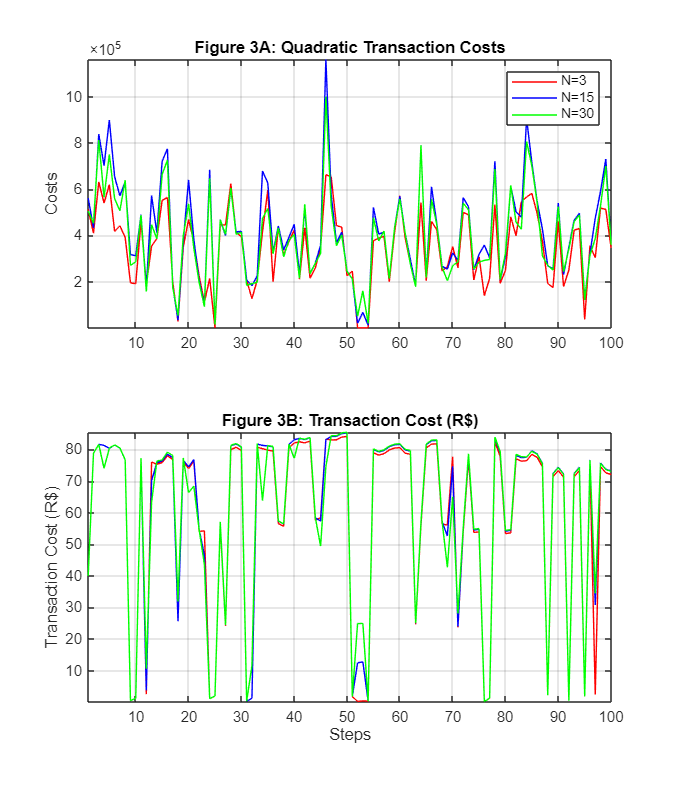


% FIGURA 3: Costi di Transazione
figure('Color', 'w', 'Position', [750, 100, 600, 700]);

subplot(2,1,1);
plot(giorni_asse_x, Quad_Cost_storico(:, 1), 'r'); hold on;
plot(giorni_asse_x, Quad_Cost_storico(:, 2), 'b');
plot(giorni_asse_x, Quad_Cost_storico(:, 3), 'g');
title('Figure 3A: Quadratic Transaction Costs');
ylabel('Costs'); legend('N=3', 'N=15', 'N=30');
grid on; axis tight;

subplot(2,1,2);
plot(giorni_asse_x, True_Cost_storico(:, 1), 'r'); hold on;
plot(giorni_asse_x, True_Cost_storico(:, 2), 'b');
plot(giorni_asse_x, True_Cost_storico(:, 3), 'g');
title('Figure 3B: Transaction Cost (R$)');
xlabel('Steps'); ylabel('Transaction Cost (R$)');
grid on; axis tight

### 3. BLOCCO DI CODICE: FIGURE 4,5 (E 1)

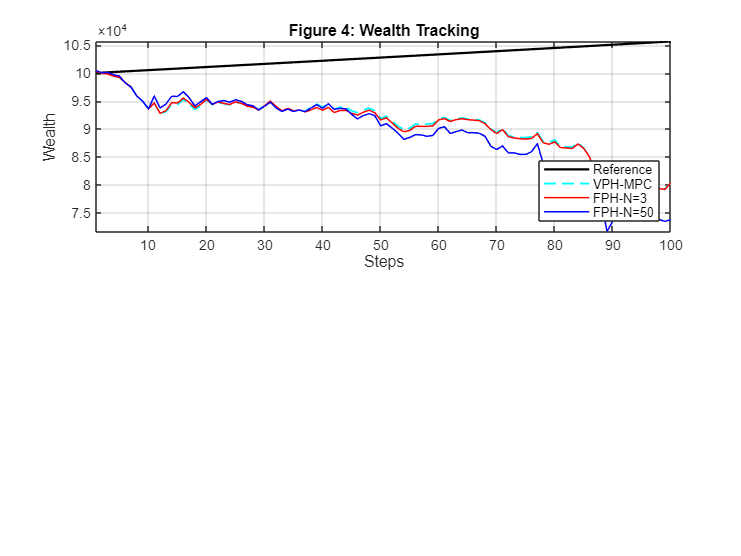

% Figure 4 e 5: VPH vs FPH Tracking
clear; clc;

% caricamento dati e parametri
data = readtable('dati_B3.csv', 'PreserveVariableNames', true);
prezzi = data{:, 2:11};          
selic_storico = data.SELIC;      
n_giorni = size(prezzi, 1); 
n_assets = size(prezzi, 2); 
n_vars = n_assets + 1;      

% calcolo dei rendimenti logaritmici
rendimenti = log(prezzi(2:end, :) ./ prezzi(1:end-1, :));

% inizializzazione dei parametri del modello
w0 = 100000;                              
mu_0_annuale = 0.15;                      
mu_0 = (1 + mu_0_annuale)^(1/252) - 1;    

% costi di transazione
c_risk = 0.0004; 
c_vec = [0; repmat(c_risk, n_assets, 1)]; 
R_cost = diag([1e-6; repmat(1e-5, n_assets, 1)]); 
rho = 1; 

% orizzonti di previsione (specificati dagli autori)
N_list = [3, 5, 10, 15, 20, 30, 50];
n_horizons = length(N_list);

% parametri di simulazione
start_k = 60;         
giorni_simulazione = 100; 

% utilizziamo Sequential Quadratic Programming (SQP)
options = optimoptions('fmincon', 'Algorithm', 'sqp', 'Display', 'none');

% --- ADDESTRAMENTO VAR(1) (sui primi 60 giorni) ---
train_data = rendimenti(1:60, :);
Mdl = varm(n_assets, 1);
EstMdl = estimate(Mdl, train_data, 'Display', 'off');
A1 = EstMdl.AR{1};

% buffer per il salvataggio dei risultati
w_ref_storico = zeros(giorni_simulazione, 1);
w_storico_FPH = zeros(giorni_simulazione, n_horizons);
w_storico_VPH = zeros(giorni_simulazione, 1);

% stato attuale del riferimento
w_ref_k = w0;

% stati attuali per le strategie FPH (uno per ogni N)
w_k_FPH = repmat(w0, 1, n_horizons);
u_prev_FPH = zeros(n_vars, n_horizons);

% stati attuali per la strategia VPH
w_k_VPH = w0;
u_prev_VPH = zeros(n_vars, 1);

% buffer per accumulare il tempo di esecuzione per ogni orizzonte
Time_FPH = zeros(1, n_horizons);
Time_VPH = zeros(1, n_horizons);

% --- LOOP MPC (strategie implementate: FPH e VPH) ---
% OSS. --> FPH-MPC: come evidenziato dagli autori, FPH fa evolvere le ricchezze corrispondenti 
%          ai sette orizzonti di previsione, in maniera del tutto indipendente
%
% OSS. --> VPH-MPC: a differenza di FPH-MPC, ogni giorno prova a simulare cosa accadrebbe utilizzando i sette orizzonti di previsione, pertanto,
%          valuta il costo previsto di ciascuna scelta e applica solo quella che gli garantisce il costo minore per quel giorno. VPH risolve sette problemi di ottimizzazione ad ogni step
for step = 1:giorni_simulazione
    k = start_k + step - 1;
    
    % --- PARTE COMUNE a FPH-MPC e VPH-MPC ---
    % finestra mobile di 60 giorni
    % --> stimiamo i rendimenti futuri usando la media campionaria recente
    mu_hat = mean(rendimenti(k-59:k, :))';
    v_hat = (eye(n_assets) - A1) * mu_hat; % Aggiornamento parametri VAR(1) al tempo k
    
    % definiamo il tasso risk-free atteso come il tasso di SELIC al giorno k
    r1_hat = selic_storico(k);

    % predizione rendimenti futuri sull'orizzonte N massimo (N=50) per riutilizzarle
    eta_pred_max = zeros(n_assets, max(N_list));
    eta_curr = rendimenti(k, :)';
    
    for h = 1:max(N_list)
        if h == 1
            eta_pred_max(:, h) = v_hat + A1 * eta_curr;
        else
            eta_pred_max(:, h) = v_hat + A1 * eta_pred_max(:, h-1);
        end
    end
    
    % rendimenti e costi reali
    ret_oggi = rendimenti(k+1, :)'; 
    r1_oggi = selic_storico(k+1);
    crescita_oggi = [(1 + r1_oggi); exp(ret_oggi)];

    % aggiornamento riferimento
    w_ref_k = (1 + mu_0) * w_ref_k;
    w_ref_storico(step) = w_ref_k;

    % buffer utilizzato per VPH
    J_val_VPH_temp = zeros(1, n_horizons);
    u_app_VPH_temp = zeros(n_vars, n_horizons);

    % --- RISOLUZIONE OCP PER TUTTI GLI ORIZZONTI ---
    for j = 1:n_horizons
        N = N_list(j);

        % estraiamo solo la porizione di previsione utile
        eta_pred = eta_pred_max(:, 1:N);
        
        % vincoli
        lb = zeros(n_vars * N, 1);
        ub = []; 
        
        % --- simulazione FPH per orizzonte N ---
        % impostazione Variabili Decisionali iniziali
        u_init_FPH = repmat(w_k_FPH(j) / n_vars, n_vars * N, 1);
        
        % risoluzione del Problema di Controllo Ottimo (OCP)
        cost_func_FPH = @(U) calcolo_mpc_cost(U, w_k_FPH(j), u_prev_FPH(:, j), eta_pred, r1_hat, mu_0, N, n_assets, R_cost, rho);
        vincoli_func_FPH = @(U) vincoli_mpc(U, w_k_FPH(j), eta_pred, r1_hat, N, n_assets);
        
        % inizio cronometro FPH (per la figura 1)
        t_start_FPH = tic;

        U_opt_FPH = fmincon(cost_func_FPH, u_init_FPH, [], [], [], [], lb, ub, vincoli_func_FPH, options);
        
        % fine cronometro FPH e accumulo
        Time_FPH(j) = Time_FPH(j) + toc(t_start_FPH);

        % applicazione dell'azione di controllo e avanzamento
        % OSS. --> prendiamo solo l'allocazione del primo giorno
        u_app_FPH = U_opt_FPH(1:n_vars);
        
        % costi lineari trattenuto dal portafoglio
        true_cost_FPH = sum(c_vec .* abs(u_app_FPH - crescita_oggi .* u_prev_FPH(:, j)));
        
        % evoluzione della dinamica della ricchezza del portafoglio
        w_k_FPH(j) = sum(crescita_oggi .* u_app_FPH) - true_cost_FPH;
        
        % aggiornamento per lo step successivo
        u_prev_FPH(:, j) = u_app_FPH;
        
        % salvataggio nel buffer
        w_storico_FPH(step, j) = w_k_FPH(j);

      
        % --- simulazione VPH partendo dallo stato VPH  ---
        % impostazione Variabili Decisionali iniziali
        u_init_VPH = repmat(w_k_VPH / n_vars, n_vars * N, 1);
        
        % risoluzione del Problema di Controllo Ottimo (OCP)
        cost_func_VPH = @(U) calcolo_mpc_cost(U, w_k_VPH, u_prev_VPH, eta_pred, r1_hat, mu_0, N, n_assets, R_cost, rho);
        vincoli_func_VPH = @(U) vincoli_mpc(U, w_k_VPH, eta_pred, r1_hat, N, n_assets);
        
        % inizio cronometro FPH (per la figura 1)
        t_start_VPH = tic;

        [U_opt_VPH, J_val] = fmincon(cost_func_VPH, u_init_VPH, [], [], [], [], lb, ub, vincoli_func_VPH, options);

        % fine cronometro FPH e accumulo
        Time_VPH(j) = Time_VPH(j) + toc(t_start_VPH);

        % aggiornamento per lo step successivo
        % OSS. --> prendiamo solo l'allocazione del primo giorno
        u_app_VPH_temp(:, j) = U_opt_VPH(1:n_vars);

        % salvataggio nel buffer "temporaneo"
        J_val_VPH_temp(j) = J_val;

    end

    % --- APPLICAZIONE AZIONE VPH ---
    % OSS. --> scegliamo l'orizzonte che ha restituito la Funzione di Costo minore
    [~, idx_best_VPH] = min(J_val_VPH_temp);
    u_app_VPH = u_app_VPH_temp(:, idx_best_VPH);
    
    % costi lineari trattenuto dal portafoglio
    true_cost_VPH = sum(c_vec .* abs(u_app_VPH - crescita_oggi .* u_prev_VPH));
    
    % evoluzione della dinamica della ricchezza del portafoglio
    w_k_VPH = sum(crescita_oggi .* u_app_VPH) - true_cost_VPH;
    
    % aggiornamento allo step successivo
    u_prev_VPH = u_app_VPH;
    
    % salvataggio nel buffer
    w_storico_VPH(step) = w_k_VPH;
end

% --- calcolo RMSE ---
% OSS. --> RMSE (Root Mean Square Error) ha l'obiettivo di quantificare l'errore medio tra 
%          la traiettoria reale del portafoglio e la curva di riferimento desiderata inizializzazione
RMSE_FPH = zeros(1, n_horizons);

% calcolo
for j = 1:n_horizons
    RMSE_FPH(j) = sqrt(sum((w_storico_FPH(:, j) - w_ref_storico).^2) / giorni_simulazione);
end

% --- visualizzazione Figura 4 (Tracking VPH vs FPH) ---
% OSS. --> nel grafico corrispondente presentato nel paper raffigurano 
%          solo i risultati ottenuti con gli orizzonti N=3 e N=50
idx_N3 = find(N_list == 3);
idx_N50 = find(N_list == 50);

figure('Name', 'Figura 4: Tracking Performance', 'Position', [100, 100, 800, 600]);

% Figura 4
subplot(2,1,1);
plot(w_ref_storico, 'k', 'LineWidth', 1.5); hold on;
plot(w_storico_VPH, 'c--', 'LineWidth', 1.2);
plot(w_storico_FPH(:, idx_N3), 'r', 'LineWidth', 1);
plot(w_storico_FPH(:, idx_N50), 'b', 'LineWidth', 1);
title('Figure 4: Wealth Tracking');
xlabel('Steps'); ylabel('Wealth');
legend('Reference', 'VPH-MPC', 'FPH-N=3', 'FPH-N=50', 'Location', 'southeast');
grid on;
axis tight

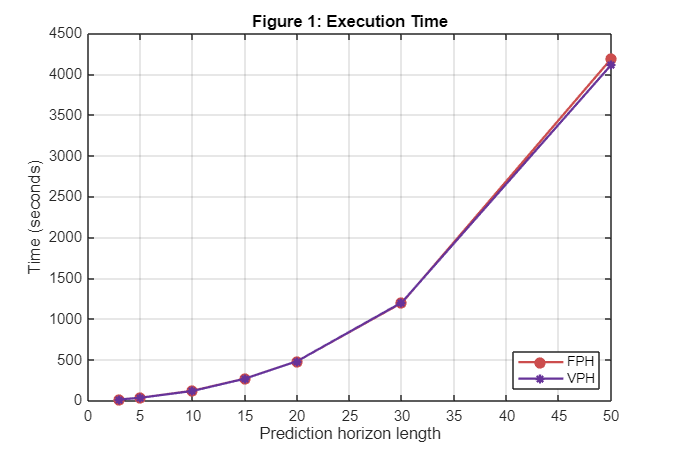


% Figura 1: tempo di esecuzione
figure('Name', 'Figura 1: Execution Time', 'Position', [100, 100, 600, 400]);
plot(N_list, Time_FPH, '-o', 'Color', [0.8 0.3 0.3], 'LineWidth', 1.5, 'MarkerFaceColor', [0.8 0.3 0.3]); hold on;
plot(N_list, Time_VPH, '-*', 'Color', [0.4 0.2 0.6], 'LineWidth', 1.5, 'MarkerFaceColor', [0.4 0.2 0.6]);

title('Figure 1: Execution Time');
xlabel('Prediction horizon length');
ylabel('Time (seconds)');
legend('FPH', 'VPH', 'Location', 'southeast');
grid on;

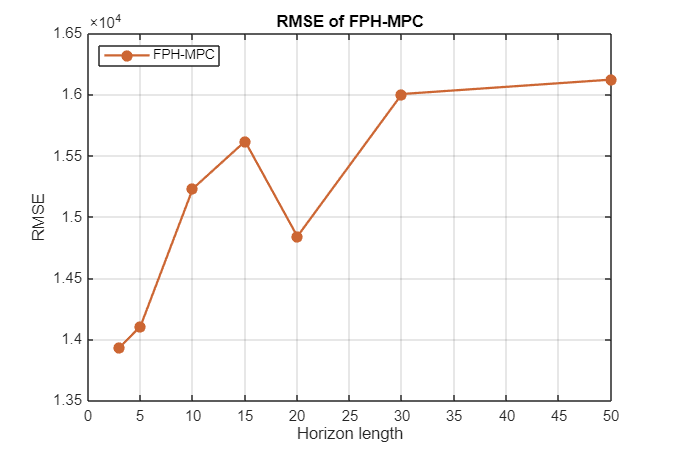

% --- visualizzazione Figura 5 (RMSE FPH) ---
figure('Name', 'Figure 5: RMSE FPH-MPC', 'Position', [950, 100, 600, 400]);
plot(N_list, RMSE_FPH, '-o', 'Color', [0.8 0.4 0.2], 'LineWidth', 1.5, 'MarkerFaceColor', [0.8 0.4 0.2]);
title('RMSE of FPH-MPC');
xlabel('Horizon length'); ylabel('RMSE');
legend('FPH-MPC', 'Location', 'northwest');
grid on;

### 4. BLOCCO DI CODICE: FIGURE 6, 7

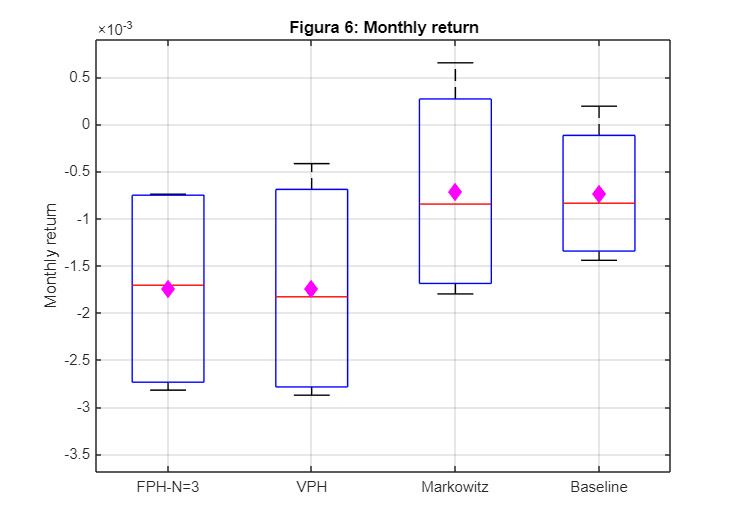

% Figura 6 e 7: Strategie di Confronto e Statistiche Mensili

% inizializzazione delle strutture dati per le strategie di MARKOWITZ e BASELINE
% il portafoglio parte con 100.000 R$ per entrambe le strategie.
w_k_markowitz = w0;
w_k_baseline  = w0;

% vettori delle allocazioni al passo precedente 
u_prev_markowitz = zeros(n_vars, 1);
u_prev_baseline  = zeros(n_vars, 1);

% vettori storici per salvare la ricchezza giorno per giorno
w_storico_markowitz = zeros(giorni_simulazione, 1);
w_storico_baseline  = zeros(giorni_simulazione, 1);

% --- LOOP (Strategie di Markowitz e Baseline) ---
% OSS. --> Modello di Markowitz: non cerca di inseguire una "curva di riferimento", il suo unico scopo è di minimizzare il 
%          rischio matematico (varianza del portafoglio), assicurando di guadagnare almeno il 15% annuo atteso. Usa, pertanto, la matrice
%          di covarianza (per evidenziare come gli asset si muovono l'uno rispetto all'altro) per trovare la combinazione di pesi per
%          cercare di annullare le oscillazioni. Tuttavia, essendo un calcolo istantaneo, appena la covarianza cambia, Markowitz
%          stravolge completamente il portafoglio.
%
% OSS. --> Baseline: utilizza lo stesso identico modello matematico del nostro controllore MPC (funzione di costo quadratica per il tracking e
%          costi di transazione). Tuttavia è un MPC che non riesce a "vedere" il futuro lungo 3, 15, 30 giorni (come fa il nostro MPC), ma si basa solo su
%          ciò che accadrà nel futuro prossimo, cioè "domani".
for step = 1:giorni_simulazione
    % Indice assoluto nel dataset (parte da 60)
    k = start_k + step - 1;
    
    % --- INFORMAZIONI DISPONIBILI AL TEMPO k (Fase di Previsione) ---
    % Rendimento medio atteso (basato sulla finestra mobile di 60 giorni storici)
    mu_hat = mean(rendimenti(k-59:k, :))'; 
    
    % Matrice di Covarianza (necessaria per calcolare il Rischio di Markowitz)
    cov_hat = cov(rendimenti(k-59:k, :)); 
    
    % Tasso dell'asset privo di rischio (Selic) al giorno corrente
    r1_hat = selic_storico(k);
    
    % --- INFORMAZIONI DEL GIORNO k+1 (Fase di Verifica sul Mercato Reale) ---
    ret_oggi = rendimenti(k+1, :)'; 
    r1_oggi = selic_storico(k+1);
    crescita_oggi = [(1 + r1_oggi); exp(ret_oggi)]; % Crescita reale di [u0, u1...u10]
    

    % --- strategia di MARKOWITZ ---
    % OSS. --> come esplicitato nel paper, Markowitz ottimizza il rischio (varianza) e il 
    %          rendimento usando gli stessi parametri. L'obiettivo matematico è:
    %          Minimizzare Varianza (Rischio) soggetto a Rendimento_Atteso >= Target.
    
    u_init_mark = repmat(w_k_markowitz / n_vars, n_vars, 1);

    % FUNZIONE OBIETTIVO: Minimizzare la varianza. Richiamiamo la 
    % funzione locale esplicita creata con il doppio ciclo 'for'.
    cost_mark = @(U) calcolo_costo_markowitz(U, cov_hat, n_assets);
    
    % VINCOLO DI UGUAGLIANZA (Aeq*x = beq): 
    % Il totale investito (somma delle u) deve essere pari al capitale disponibile.
    Aeq = ones(1, n_vars); 
    beq = w_k_markowitz;
    
    % VINCOLO DI DISUGUAGLIANZA (A*x <= b): 
    % Il rendimento atteso del portafoglio deve superare il target del paper (15% annuo).
    % Poiché fmincon accetta solo vincoli del tipo "Minore o Uguale", moltiplichiamo l'equazione per -1.
    crescita_attesa = [(1 + r1_hat); (1 + mu_hat)];
    A_ineq = -crescita_attesa'; 
    b_ineq = -w_k_markowitz * (1 + mu_0);

    % [BOUNDS]: Niente posizioni corte (lb = 0). 
    % Massimo 60% nel risk-free (ub_mark(1)), e massimo l'intero capitale
    % per le altre azioni (ub_mark(2:end)).
    lb_mark = zeros(n_vars, 1); 
    ub_mark = [0.6 * w_k_markowitz; repmat(w_k_markowitz, n_assets, 1)]; 
    
    % Ottimizzazione
    U_opt_mark = fmincon(cost_mark, u_init_mark, A_ineq, b_ineq, Aeq, beq, lb_mark, ub_mark, [], options);
    
    % Calcolo costi di transazione e aggiornamento portafoglio reale
    true_cost_mark = sum(c_vec .* abs(U_opt_mark - crescita_oggi .* u_prev_markowitz));
    w_k_markowitz = sum(crescita_oggi .* U_opt_mark) - true_cost_mark;
    w_storico_markowitz(step) = w_k_markowitz;
    u_prev_markowitz = U_opt_mark;

    % --- strategia BASELINE ---
    % OSS. --> Il paper definisce questa Baseline come un tracking non multiperiodo,
    %          ovvero un MPC che guarda a 1 solo passo nel futuro.
    u_init_base = repmat(w_k_baseline / n_vars, n_vars, 1);
    
    % calcoliamo la predizione VAR(1) per un solo giorno (N=1)
    v_hat = (eye(n_assets) - A1) * mu_hat; % Intercetta ricalibrata
    eta_pred_base = v_hat + A1 * rendimenti(k, :)';
    
    % usiamo la stessa funzione di costo dell'MPC, ma passando N=1
    cost_base = @(U) calcolo_mpc_cost(U, w_k_baseline, u_prev_baseline, eta_pred_base, r1_hat, mu_0, 1, n_assets, R_cost, rho);
    vincoli_base = @(U) vincoli_mpc(U, w_k_baseline, eta_pred_base, r1_hat, 1, n_assets);
    
    % ottimizzazione
    U_opt_base = fmincon(cost_base, u_init_base, [], [], [], [], lb_mark, [], vincoli_base, options);
    
    % calcolo costi e aggiornamento reale
    true_cost_base = sum(c_vec .* abs(U_opt_base - crescita_oggi .* u_prev_baseline));
    w_k_baseline = sum(crescita_oggi .* U_opt_base) - true_cost_base;
    w_storico_baseline(step) = w_k_baseline;
    u_prev_baseline = U_opt_base;
end

% --- AGGREGAZIONE DATI MENSILI ---
% OSS. --> un mese di contrattazione borsistica ha mediamente 21 giorni
giorni_per_mese = 21; 
num_mesi = floor(giorni_simulazione / giorni_per_mese); % arrotonda all'intero più vicino minore o uguale 

% matrici Risultati: Colonne = [FPH_N3, VPH, Markowitz, Baseline]
Monthly_Returns = zeros(num_mesi, 4);
Monthly_Risks   = zeros(num_mesi, 4);

% Calcoliamo le serie storiche dei rendimenti GIORNALIERI per tutte le strategie.
% Il rendimento giornaliero = (Ricchezza_Oggi - Ricchezza_Ieri) / Ricchezza_Ieri.
% Estraiamo la colonna 1 (N=3) da w_storico_FPH (già calcolata nel blocco precedente).
w_storico_FPH_N3 = w_storico_FPH(:, 1);

ret_giornalieri_FPH  = diff(w_storico_FPH_N3)    ./ w_storico_FPH_N3(1:end-1);
ret_giornalieri_VPH  = diff(w_storico_VPH)       ./ w_storico_VPH(1:end-1);
ret_giornalieri_Mark = diff(w_storico_markowitz) ./ w_storico_markowitz(1:end-1);
ret_giornalieri_Base = diff(w_storico_baseline)  ./ w_storico_baseline(1:end-1);

% Ciclo sui mesi per calcolare la media e la deviazione standard
for m = 1:num_mesi
    idx_start = (m - 1) * giorni_per_mese + 1;
    idx_end   = m * giorni_per_mese;
    
    % RENDIMENTO MENSILE (Media dei rendimenti giornalieri nel mese) -> Figura 6
    Monthly_Returns(m, 1) = mean(ret_giornalieri_FPH(idx_start:idx_end));
    Monthly_Returns(m, 2) = mean(ret_giornalieri_VPH(idx_start:idx_end));
    Monthly_Returns(m, 3) = mean(ret_giornalieri_Mark(idx_start:idx_end));
    Monthly_Returns(m, 4) = mean(ret_giornalieri_Base(idx_start:idx_end));
    
    % RISCHIO MENSILE (Deviazione Standard dei rendimenti nel mese) -> Figura 7
    Monthly_Risks(m, 1) = std(ret_giornalieri_FPH(idx_start:idx_end));
    Monthly_Risks(m, 2) = std(ret_giornalieri_VPH(idx_start:idx_end));
    Monthly_Risks(m, 3) = std(ret_giornalieri_Mark(idx_start:idx_end));
    Monthly_Risks(m, 4) = std(ret_giornalieri_Base(idx_start:idx_end));
end

% --- FIGURA 6: BOXPLOT RENDIMENTO MENSILE ---
figure('Name', 'Figura 6: Monthly Return', 'Position', [100, 100, 700, 500]);
boxplot(Monthly_Returns, 'Labels', {'FPH-N=3', 'VPH', 'Markowitz', 'Baseline'});
title('Figura 6: Monthly return');
ylabel('Monthly return');
grid on; hold on;

% Dettaglio estetico del paper: Il rombo magenta indica il valore medio esatto.
plot(1:4, mean(Monthly_Returns, 1), 'md', 'MarkerFaceColor', 'm', 'MarkerSize', 8);

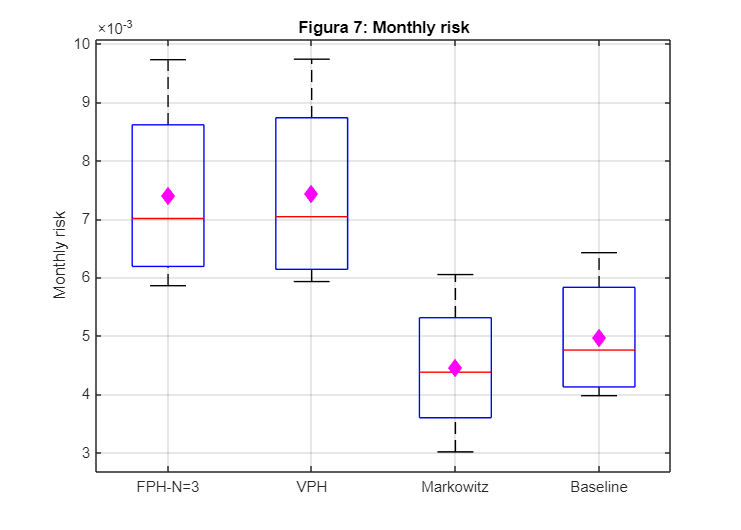


% --- FIGURA 7: BOXPLOT RISCHIO MENSILE ---
figure('Name', 'Figura 7: Monthly Risk', 'Position', [850, 100, 700, 500]);
boxplot(Monthly_Risks, 'Labels', {'FPH-N=3', 'VPH', 'Markowitz', 'Baseline'});
title('Figura 7: Monthly risk');
ylabel('Monthly risk');
grid on; hold on;

% Rombo magenta per la media del rischio
plot(1:4, mean(Monthly_Risks, 1), 'md', 'MarkerFaceColor', 'm', 'MarkerSize', 8);

### BLOCCO CODICE: 8,9

% Figure 8,9 e Tabelle 1,2: Confronto con i Benchmark citati e Ottimizzazione CVaR

% --- estrazione dell'indice Ibovespa dal dataset ---
ibov_prezzi = data.IBOV(60:60+giorni_simulazione); 
ret_ibov = log(ibov_prezzi(2:end) ./ ibov_prezzi(1:end-1));

w_storico_ibov = zeros(giorni_simulazione, 1);
w_storico_ibov(1) = w0;

for t = 2:giorni_simulazione
    w_storico_ibov(t) = w_storico_ibov(t-1) * exp(ret_ibov(t-1));
end

% --- CALCOLO TABELLA 1: INDICE DI SHARPE ---

% calcolo Indice di Sharpe grazie alla funzione locale
SR_VPH = calcolo_sharpe_ratio(w_storico_VPH, w_ref_storico);
SR_FPH3 = calcolo_sharpe_ratio(w_storico_FPH(:,1), w_ref_storico); % --> FPH (N=3)
SR_Mark = calcolo_sharpe_ratio(w_storico_markowitz, w_ref_storico);
SR_Ibov = calcolo_sharpe_ratio(w_storico_ibov, w_ref_storico);
SR_Base = calcolo_sharpe_ratio(w_storico_baseline, w_ref_storico);

fprintf('\n--- TABELLA 1: Indice di Sharpe ---\n');


--- TABELLA 1: Indice di Sharpe ---


fprintf('VPH: %.2f | FPH-N=3: %.2f | Markowitz: %.2f | Ibovespa: %.2f | Baseline: %.2f\n', ...
        SR_VPH, SR_FPH3, SR_Mark, SR_Ibov, SR_Base);

VPH: -4.02 | FPH-N=3: -3.98 | Markowitz: -1.89 | Ibovespa: -3.02 | Baseline: -3.90


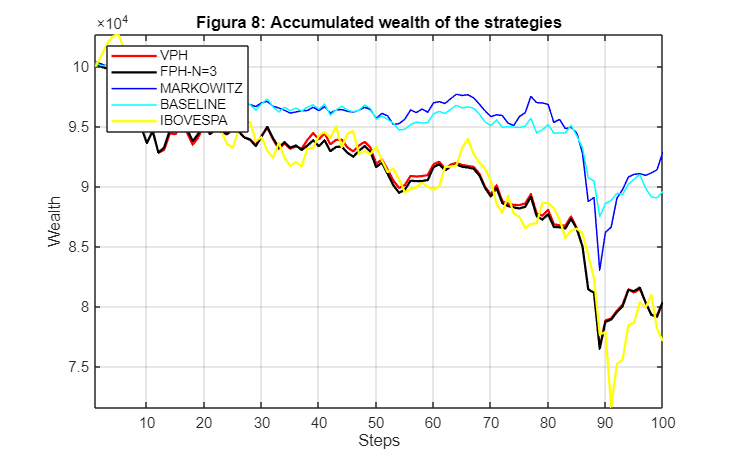


% Figura 8: ricchezza accumulata
figure('Name', 'Figura 8: Wealth tracking benchmarks', 'Position', [100, 100, 800, 500]);
plot(w_storico_VPH, 'r', 'LineWidth', 1.5); hold on;
plot(w_storico_FPH(:,1), 'k', 'LineWidth', 1.5);
plot(w_storico_markowitz, 'b', 'LineWidth', 1);
plot(w_storico_baseline, 'c', 'LineWidth', 1);
plot(w_storico_ibov, 'y', 'LineWidth', 1.5);

title('Figura 8: Accumulated wealth of the strategies');
ylabel('Wealth'); xlabel('Steps');
legend('VPH', 'FPH-N=3', 'MARKOWITZ', 'BASELINE', 'IBOVESPA',  'Location', 'northwest');
grid on;
axis tight


% --- OTTIMIZZAZIONE CVaR (FPH-CVaR per N=3 e N=5) ---
% OSS. --> la metrica CVaR ci permette di rappresenta il valore atteso di tutte le perdite che eccedono la soglia impostata (95%). Minimizzando
%          tale media, dei peggiori scenari stocastici, il controllore, come evidenziato dagli autori, traccia il benchmark "dall'alto", cercando di
%          superarlo e offrendo una protezione maggiore contro le oscillazioni del mercato

% OSS. --> parametri esplicitati nel paper
beta_cvar = 0.95;     % Livello di confidenza 95% 
M_scenarios = 100;    % Numero di scenari generati 
N_cvar_list = [3, 5]; % Orizzonti analizzati per CVaR

w_storico_cvar = zeros(giorni_simulazione, length(N_cvar_list));
w_k_cvar = repmat(w0, 1, length(N_cvar_list));
u_prev_cvar = zeros(n_vars, length(N_cvar_list));

% Modifichiamo le options per permettere più iterazioni, vista la complessità
% OSS. --> optimoptions: serve a definire le impostazioni personalizzate da passare al solutore matmatico fmincon. 
%          Andiamo a vedere cosa fanno i vari i due parametri più importanti:
%           - fmincon: nome della funzione che esegue l'ottimizzazione (ci permette di trovare il minimo di una funzione multivariabile non lineare vincolata)
%           - sqp: comando che esplicita l'utilizzo dell'algoritmo SQP
options_cvar = optimoptions('fmincon', 'Algorithm', 'sqp', 'Display', 'none', 'MaxFunctionEvaluations', 10000);


for step = 1:giorni_simulazione
    k = start_k + step - 1;
    
    % finestra mobile di 60 giorni
    % --> stimiamo i rendimenti futuri usando la media campionaria recente
    mu_hat = mean(rendimenti(k-59:k, :))';
    v_hat = (eye(n_assets) - A1) * mu_hat; % Aggiornamento parametri VAR(1) al tempo k
    
    % matrice covarianza per il rumore bianco e(k)
    cov_hat = cov(rendimenti(k-59:k, :));
    
    % definiamo il tasso risk-free atteso come il tasso di SELIC al giorno k
    r1_hat = selic_storico(k);
    
    % rendimenti e costi reali
    ret_oggi = rendimenti(k+1, :)'; 
    r1_oggi = selic_storico(k+1);

    % vettore_crescita: u0 cresce con r1_oggi, le azioni con ret_oggi
    crescita_oggi = [(1 + r1_oggi); exp(ret_oggi)];
    
    for idx_n = 1:length(N_cvar_list)
        N = N_cvar_list(idx_n);
        
        % GENERAZIONE DEGLI SCENARI 
        % OSS. --> Come da Equazione (21) del paper, inseriamo una componente stocastica "e(k+j+1)". 
        %          Generiamo un rumore casuale basato sulla matrice di covarianza: mvrnd(), Multivariate Normal Random Numbers
  
        % Matrice 3D: [n_assets x N x M_scenarios]
        scenari_eta = zeros(n_assets, N, M_scenarios);
        
        for m = 1:M_scenarios
            
            % estrazione rumore bianco multivariato per N passi
            e_noise = mvnrnd(zeros(n_assets,1), cov_hat, N)'; 
            
            % predizione rendimenti futuri sull'orizzonte N
            eta_temp = zeros(n_assets, N);
            eta_curr = rendimenti(k, :)';
            
            for h = 1:N
                if h == 1 
                    eta_temp(:, h) = v_hat + A1 * eta_curr + e_noise(:, h);
                else     
                    eta_temp(:, h) = v_hat + A1 * eta_temp(:, h-1) + e_noise(:, h);
                end
            end
            
            % predizione rendimenti futuri sull'orizzonte N corrispondente allo scenario m
            scenari_eta(:, :, m) = eta_temp;
        
        end
        
        % --- IMPOSTAZIONE VARIABILI DI DECISIONE E LIMITI ---
        % OSS. --> Per il CVaR, la variabile di decisione X è composta da:
        %               X(1:n_vars*N) -> Allocazioni U
        %               X(end)        -> Valore di xi (il VaR stimato)
        
        % impostazione Variabili Decisionali iniziali
        u_init = repmat(w_k_cvar(idx_n) / n_vars, n_vars * N, 1);
        
        xi_init = 0; 
        X_init = [u_init; xi_init];
        
        % i limiti lb e ub si applicano solo a U, xi è libera
        lb_cvar = [zeros(n_vars * N, 1); -Inf];
        ub_cvar = [];
        
        % risoluzione del Problem di Controllo Ottimo (OCP)
        cost_func_cvar = @(X) calcolo_costo_cvar(X, w_k_cvar(idx_n), u_prev_cvar(:, idx_n), scenari_eta, r1_hat, mu_0, N, n_assets, R_cost, rho, beta_cvar, M_scenarios);
        vincoli_cvar = @(X) vincoli_mpc_cvar(X, w_k_cvar(idx_n), mean(scenari_eta, 3), r1_hat, N, n_assets);
        
        % OSS. --> X_opt viene fuori solo quando fmincon riesce a trovare la combinazione (U,xi) in grado di rendere il costo il più basso
        %          possibile. Prima di X_opt, genera, migliaia di volte X che viene valutata dalle funzioni di cui sopra
        X_opt = fmincon(cost_func_cvar, X_init, [], [], [], [], lb_cvar, ub_cvar, vincoli_cvar, options_cvar);
        
        % estrazione dell'azione di controllo reale (solo U)
        u_app_cvar = X_opt(1:n_vars);
        
        % applicazione e calcolo costi
        true_cost = sum(c_vec .* abs(u_app_cvar - crescita_oggi .* u_prev_cvar(:, idx_n)));
        
        % w_cvar(k): valore dello stato all'istante idx_n
        w_k_cvar(idx_n) = sum(crescita_oggi .* u_app_cvar) - true_cost;
        
        % salvataggio dei risultati
        w_storico_cvar(step, idx_n) = w_k_cvar(idx_n);

        % aggiornamento per il prossimo step
        u_prev_cvar(:, idx_n) = u_app_cvar;
    end
end

% --- CALCOLO TABELLA 2: RMSE E SHARPE RATIO DEL CVaR ---
SR_CVAR_3 = calcolo_sharpe_ratio(w_storico_cvar(:, 1),w_ref_storico);
SR_CVAR_5 = calcolo_sharpe_ratio(w_storico_cvar(:, 2),w_ref_storico);

RMSE_CVAR_3 = sqrt(sum((w_storico_cvar(:, 1) - w_ref_storico).^2) / giorni_simulazione);
RMSE_CVAR_5 = sqrt(sum((w_storico_cvar(:, 2) - w_ref_storico).^2) / giorni_simulazione);

% recuperiamo l'RMSE del VPH e FPH3 dal blocco precedente
RMSE_VPH = sqrt(sum((w_storico_VPH - w_ref_storico).^2) / giorni_simulazione);
RMSE_FPH3 = sqrt(sum((w_storico_FPH(:,1) - w_ref_storico).^2) / giorni_simulazione);
RMSE_Base = sqrt(sum((w_storico_baseline - w_ref_storico).^2) / giorni_simulazione);


fprintf('\n--- TABELLA 2: Sharpe Ratio e RMSE ---\n');


--- TABELLA 2: Sharpe Ratio e RMSE ---


fprintf('Metodo       | FPH-CVaR (N=3) | FPH-CVaR (N=5) | VPH      | FPH-N=3  | Baseline \n');

Metodo       | FPH-CVaR (N=3) | FPH-CVaR (N=5) | VPH      | FPH-N=3  | Baseline 


fprintf('Sharpe Ratio | %.2f           | %.2f           | %.2f     | %.2f     | %.2f     \n', ...
        SR_CVAR_3, SR_CVAR_5, SR_VPH, SR_FPH3, SR_Base);

Sharpe Ratio | -4.56           | -4.17           | -4.02     | -3.98     | -3.90     


fprintf('RMSE         | %1.2e       | %1.2e       | %1.2e | %1.2e | %1.2e \n', ...
        RMSE_CVAR_3, RMSE_CVAR_5, RMSE_VPH, RMSE_FPH3, RMSE_Base);

RMSE         | 9.06e+03       | 8.42e+03       | 1.38e+04 | 1.39e+04 | 8.51e+03 


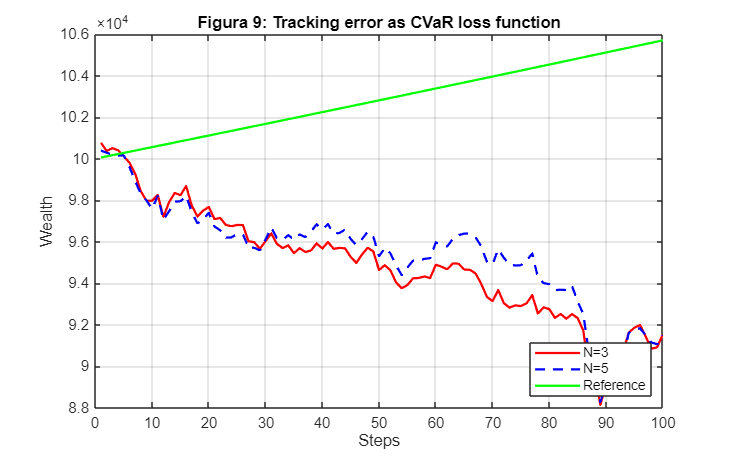


% --- FIGURA 9: TRACKING CVAR ---
figure('Name', 'Figura 9: Tracking CVaR', 'Position', [150, 150, 800, 500]);
plot(w_storico_cvar(:, 1), 'r', 'LineWidth', 1.5); hold on;
plot(w_storico_cvar(:, 2), 'b--', 'LineWidth', 1.5);
plot(w_ref_storico, 'g', 'LineWidth', 1.5);

title('Figura 9: Tracking error as CVaR loss function');
ylabel('Wealth'); xlabel('Steps');
legend('N=3', 'N=5', 'Reference', 'Location', 'southeast');
grid on;

### FUNZIONI LOCALI 

% --- FUNZIONI LOCALI utilizzate nel codice di cui sopra ---

%% 1. calcolo_mpc_cost() --> tale funzione ci permette di tradurre fedelmente l'equazione 11 del paper. L'ottimizzatore proverà migliaia di vettori U diversi e 
%                         per ogni tentativo passerà tali U a questa funzione
%                         in modo da capire quanto la scelta sia "cattiva" (quanto il valore di J, cioè della funzione di costo, sia elevato).
%                         Andiamo ad esplicitare cosa rappresentano i parametri che passiamo a tale funzione:
%                           - U: variabile decionale, rappresenta l'incognita 
%                           - w_k: stato del sistema, cioè ricchezza attuale (equazione 7 del paper)
%                           - u_prev: memoria di allocazione, cioè un vettore colonna che indica il capitale investito in ogni singolo asset nel giorno precedente alla predizione (k-1)
%                           - eta_pred: rappresenta la previsione dei rendimenti logaritmici futuri lungo l'orizzonte predittivo N
%                           - r1_hat: rendimento dell'asset privo di rischio
%                           - mu_0: il benchmark, cioè il tasso di riferimento (equazione 10 del paper)
%                           - N: orizzonte di predizione
%                           - n_assets: numero totali di azioni rischiose nel portafoglio (nel nostro caso 10 come esplicitato nel paper)
%                           - R_cost: matrice dei pesi dei costi di controllo
%                           - rho: garantisce l'assimetria del tracking error ed è peso scalare che gli autori impostano pari a 1

function J = calcolo_mpc_cost(U, w_k, u_prev, eta_pred, r1_hat, mu_0, N, n_assets, R_cost, rho)
    J = 0;
    
    % rifereimento locale come esplicitato dagli autori: w^0(k+j|k)
    w_ref = w_k;
    u_last = u_prev;
    n_vars = n_assets + 1;


    for j = 1:N
        % vettore delle crescite attese: [SELIC; AZIONE_1; ... ; AZIONE_10]
        crescita_attesa = [(1 + r1_hat); (1 + eta_pred(:, j))];

        % estraiamo le allocazioni proposte dall'ottimizzatore per lo step j
        idx_start = (j-1)*n_vars + 1;
        idx_end = j*n_vars;
        
        u_j = U(idx_start:idx_end);

        % dinamica del Portfolio di Riferimento (equazione 10 del paper)
        w_ref = (1 + mu_0) * w_ref;

        % dinamica del Portfolio Predetto
        w_pred = sum(crescita_attesa .* u_j);

        % calcolo dei Costi di Transazione Quadratici (termine 3 dell'equazione 11 del paper)
        % OSS. --> valutiamo la variazione di allocazione rispetto al giorno prima
        v_j = u_j - crescita_attesa .* u_last;
        trans_cost = v_j' * R_cost * v_j;

        % Tracking Error Asimmetrico (termini 1 e 2 dell'equazione 11)
        err = w_pred - w_ref;
        
        % aggiorniamo la funzione di costo totale J
        J = J + (err^2 - rho * err) + trans_cost;

        % prepariamo lo step successivo
        u_last = u_j;
    end
end

%% 2. vincoli_mpc() --> tale funzione ci permette di far rispettare all'ottimizzatore fmincon i vincoli di disuguaglianza 
%                       e assicurarsi che la somma delle allocazioni sia pari alla ricchezza disponibile.
%                       Andiamo ad esplicitare cosa rappresentano i parametri che passiamo a tale funzione:
%                           - U: variabile decionale, rappresenta l'incognita 
%                           - w_k: stato del sistema, cioè ricchezza attuale (equazione 7 del paper)
%                           - eta_pred: rappresenta la previsione dei rendimenti logaritmici futuri lungo l'orizzonte predittivo N
%                           - r1_hat: rendimento dell'asset privo di rischio
%                           - N: orizzonte di predizione
%                           - n_assets: numero totali di azioni rischiose nel portafoglio (nel nostro caso 10 come esplicitato nel paper)

function [c_dis, c_eq] = vincoli_mpc(U, w_k, eta_pred, r1_hat, N, n_assets)
    
    c_dis = [];         % vincolo di disuguaglianza c_dis <= 0
    c_eq = [];          % vincolo di uguaglianza c_eq == 0
    n_vars = n_assets + 1;
    w_curr = w_k;       % inizializzazione ricchezza attuale

    for j = 1:N
        idx_start = (j-1)*n_vars + 1;
        idx_end = j*n_vars;
        u_j = U(idx_start:idx_end);
        
        % Uguaglianza: la somma del capitale investito deve corrispondere alla ricchezza
        c_eq = [c_eq; sum(u_j) - w_curr];
        
        % Disuguaglianza: limite risk-free al 60% della ricchezza attuale
        c_dis = [c_dis; u_j(1) - 0.6 * w_curr];
        
        % Dinamica della ricchezza per i vincoli del passo successivo (j+1)
        crescita_attesa = [(1 + r1_hat); (1 + eta_pred(:, j))];
        w_curr = sum(crescita_attesa .* u_j);
    end
end

%% 3. calcolo_costo_markowitz() --> % Calcola esplicitamente la forma quadratica della varianza del portafoglio:
%                                     J = x^T * Cov * x (dove x sono le porzioni investite in asset rischiosi)
%                                     Andiamo ad esplicitare cosa rappresentano i parametri che passiamo a tale funzione:  
%                                           - U: variabile decionale, rappresenta l'incognita 
%                                           - cov_hat: matrice di covarianza (necessaria per calcolare il Rischio di Markowitz)
%                                           - n_assets: numero totali di azioni rischiose nel portafoglio (nel nostro caso 10 come esplicitato nel paper)

function J_mark = calcolo_costo_markowitz(U, cov_hat, n_assets)
   
    J_mark = 0;
    U_risk = U(2:end); % Escludiamo l'asset risk-free (indice 1)
    
    for i = 1:n_assets
        for j = 1:n_assets
            J_mark = J_mark + U_risk(i) * cov_hat(i,j) * U_risk(j);
        end
    end
end

%% 4. calcolo_sharpe_ratio() --> ci permette di calcolare l'equazione 27 del paper, annualizzando lo Sharpe Ratio 
%                             al fine di confrontarlo proprio come fatto dagli autori e in finanza (OSS. di cui sopra)
%                             I parametri che gli passiamo saranno:
%                               - w_storico: vettore degli stati del portafoglio valutato
%                               - w_ref_storico: vettore degli stati del portafoglio di riferimento
function SR = calcolo_sharpe_ratio(w_storico, w_ref_storico)
    
    % Questa funzione implementa il calcolo dello Sharpe Ratio
    % Formula: SR = (Media_Rendimenti - Media_Riferimento) / Deviazione_Standard
    
    % Calcolo dei rendimenti giornalieri del portafoglio valutato
    ret_giornalieri = diff(w_storico) ./ w_storico(1:end-1);
    
    % Calcolo dei rendimenti giornalieri del portafoglio di riferimento
    ret_giornalieri_ref = diff(w_ref_storico) ./ w_ref_storico(1:end-1);
    
    % OSS. --> tramite questi passaggi abbiamo implementato: (w(k) - w(k-1))/w(k-1)
    
    % Calcolo delle statistiche (Media e Deviazione Standard)
    media_ret = mean(ret_giornalieri);
    media_ref = mean(ret_giornalieri_ref);
    sigma_ret = std(ret_giornalieri);
    
    % Calcolo dello Sharpe Ratio base (su scala giornaliera)
    SR_giornaliero = (media_ret - media_ref) / sigma_ret;
    
    % Annualizzazione (Moltiplicazione per la radice dei giorni lavorativi annui)
    SR = SR_giornaliero * sqrt(252);
    
end

%% 5. calcolo_costo_cvar() -->   questa funzione implementa l'Eq (22) del paper
function f_val = calcolo_costo_cvar(X, w_k, u_prev, scenari_eta, r1_hat, mu_0, N, n_assets, R_cost, rho, beta, M)
    
    U = X(1:end-1); % Estraiamo il vettore delle decisioni U
    xi = X(end);    % Estraiamo la variabile ausiliaria xi (VaR)
    
    sum_losses = 0;
    
    % Ciclo su tutti gli M scenari per calcolare J^t(U)
    for m = 1:M
        eta_pred_m = scenari_eta(:, :, m); % Previsione del return per lo scenario m
        
        % Calcoliamo il costo J standard applicato a questo specifico scenario 
        J_m = calcolo_mpc_cost(U, w_k, u_prev, eta_pred_m, r1_hat, mu_0, N, n_assets, R_cost, rho);
        
        % [J^t - xi]^+ : Se il costo supera xi, aggiungiamo la differenza
        sum_losses = sum_losses + max(0, J_m - xi);
    end
    
    % Funzione finale CVaR = xi + (1 / ((1-beta)*M)) * sum(perdite_eccedenti)
    f_val = xi + (1 / ((1 - beta) * M)) * sum_losses;
end

%% 6. vincoli _mpc_cvar()
function [c, ceq] = vincoli_mpc_cvar(X, w_k, eta_pred_mean, r1_hat, N, n_assets)
    
    % OSS. --> Il vincolo si applica solo al vettore U, xi non è soggetta a limiti di budget
    U = X(1:end-1);

    % OSS. --> richiamiamo l'altra funzione locale da noi definita, siccome
    %          notiamo che i vincoli sono uguali nelle due formulazioni OCP
    [c, ceq] = vincoli_mpc(U, w_k, eta_pred_mean, r1_hat, N, n_assets);
end